# Example Code: Nonlinear Solver

## Problem

A soccer ball is kicked to other player at 20 meters away so he can head the ball. The target height of the ball is 2m. Find the angle at which the player must kick for the pass. Let initial velocity of the ball at the kick is 17m/s, distance x=20m, target height y=2m,  and there is no spin.  

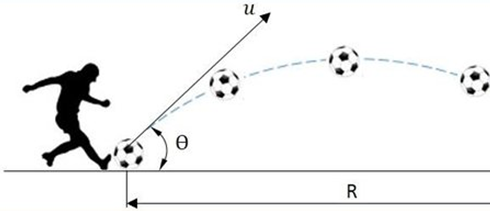     

with  x=20[m], y=2[m],v=17[m/s], g=9.8[m/s2]

### Matlab Functions

It is a non-linear equation. First, define a non-linear function in the form of f(θ)=0. 

Then, use a non-linear equation solver fzero ().

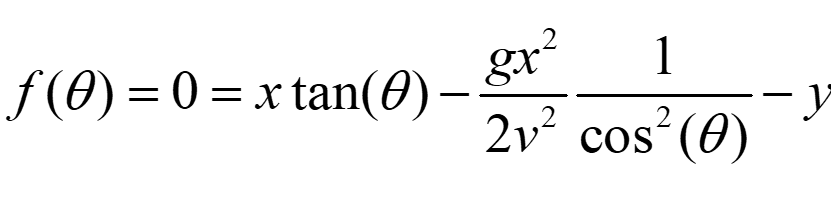

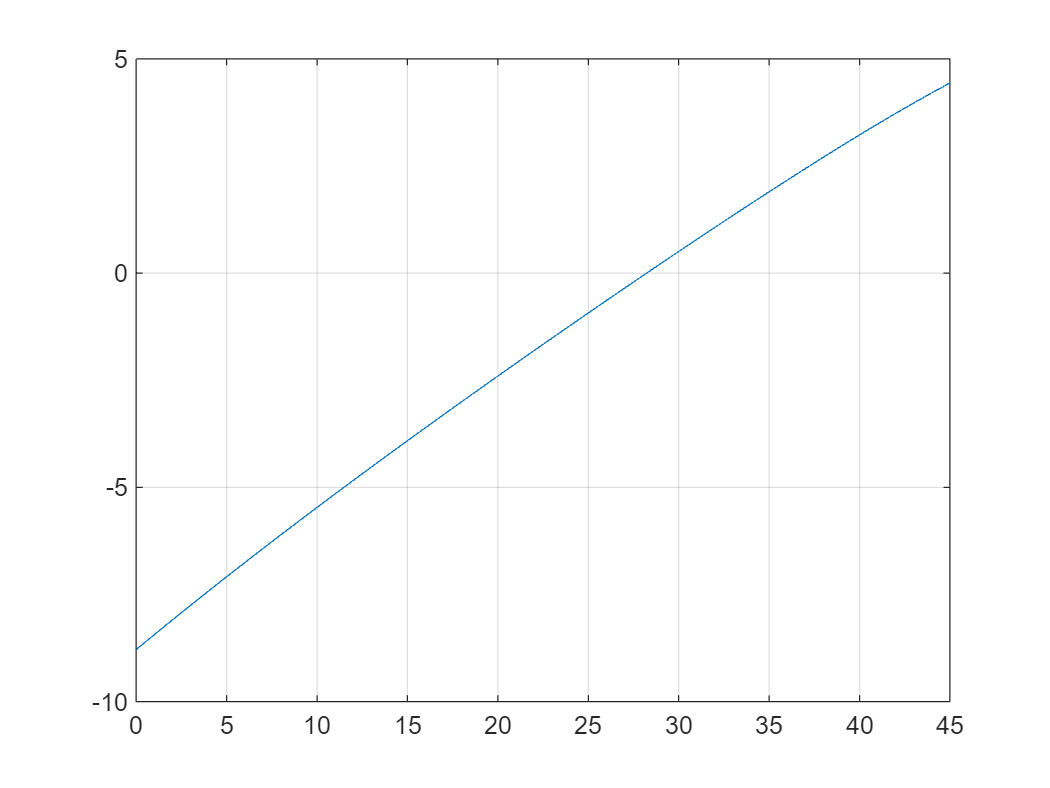

clear all

t=0:1:45;
plot(t,fnTrajectory(t)); grid on

t0=10;
sol=fzero(@fnTrajectory,t0)

sol = 28.2279

function z=fnTrajectory(t)
    x=20; y=2;v=17; g=9.8; 
    z=x.*tand(t)-g.*x.*x./(2.*v.*v.*cosd(t).*cosd(t))-y;
end

